# Read me

This mlx is thought to be executed **section by section**: the user can modify small pieces in order to express his/her preferences.

User must not modify the name of the variables!

User must click on Run Section to see the results of his/her modifications.

## Import image

This section must be run only once!!!


import iftiread.*
import niftiinfo.*

% Read the NIfTI file
data = niftiread("sub2_t1_2_t2.nii");
% Get information about the NIfTI file
info = niftiinfo("sub2_t1_2_t2.nii");
numOfGreyLevels = 2 ^ info.BitsPerPixel;

left_ventricle_volume = zeros(256,256,30);
right_ventricle_volume = zeros(256,256,30);

voxel_dim = info.PixelDimensions(1,1) * info.PixelDimensions(1,2) * info.PixelDimensions(1,3);
dimension = info.SpaceUnits;


## Slice selection

Choose the slice you want to work with by modifying the number


slice_number = 16 ;


-------------------------------------

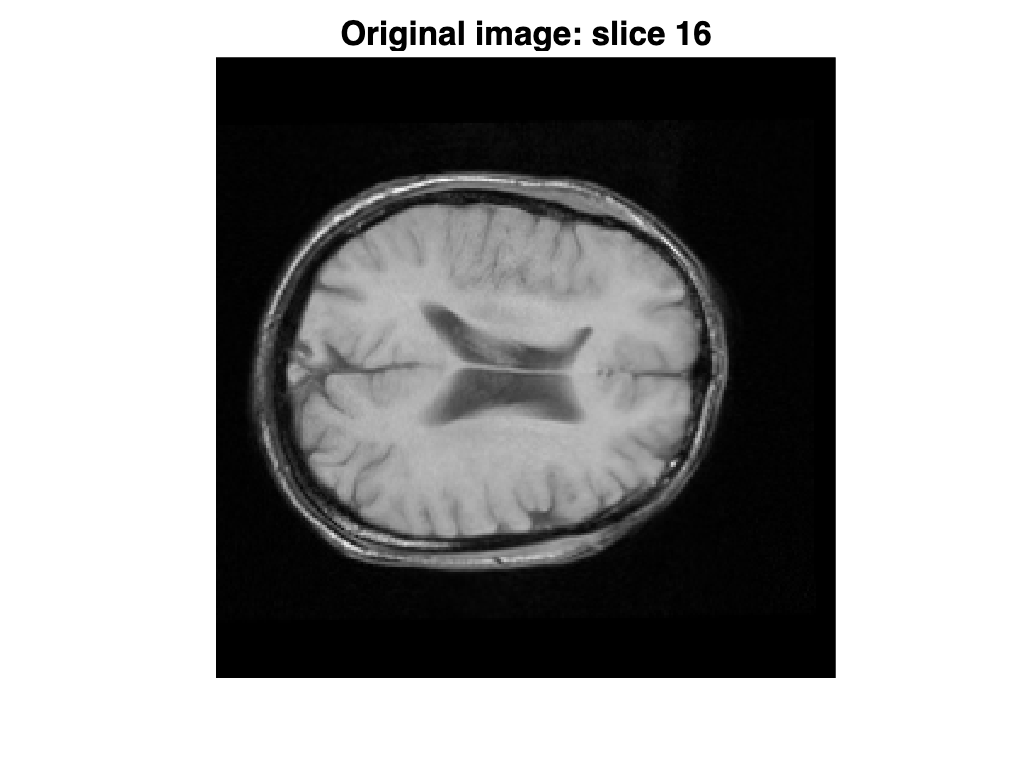


img = data(:, :, slice_number);
% Convert values to double for normalization
img = im2double(img);
% Normalize values
image = ( img - min(img(:)) )./( max(img(:)) - min(img(:)) );

figure;
imshow(image);
title([ 'Original image: slice ', num2str(slice_number) ] );

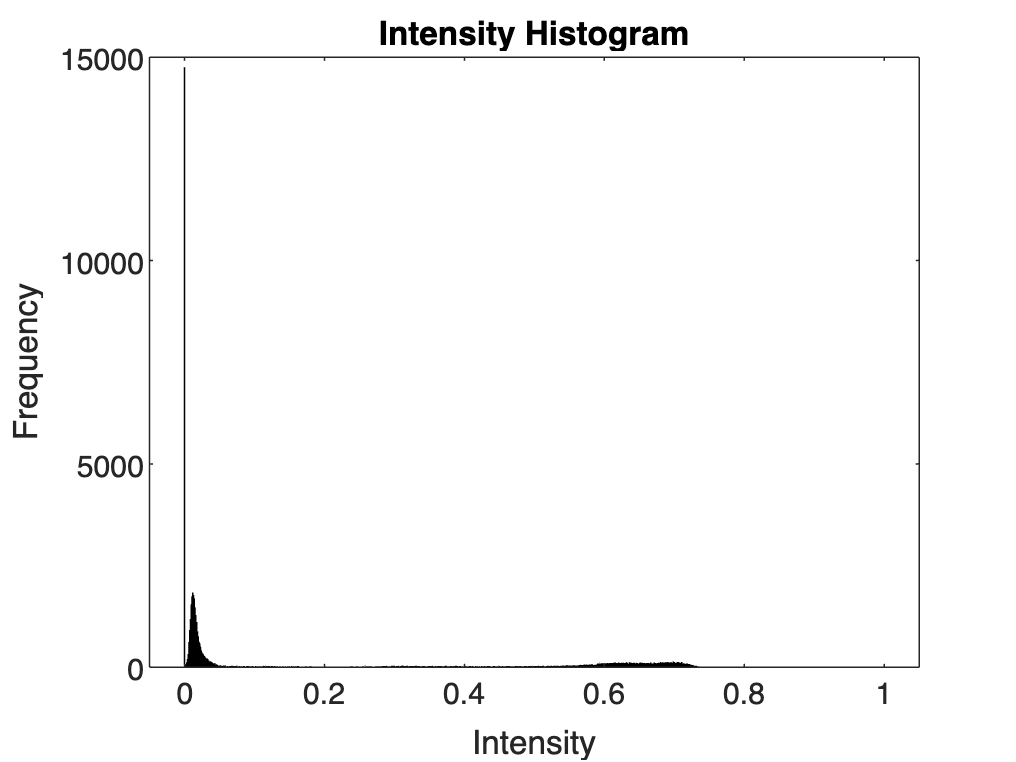


figure;
histogram(image, 'NumBins', numOfGreyLevels);
xlabel('Intensity');
ylabel('Frequency');
title('Intensity Histogram');

## Noise simulation

If you want to simulate noise on your image, select the typee of noise and its intensity, then Run Section


gaussian_mean = 0.1 ;
img_w_noise = imnoise(image,'gaussian', gaussian_mean);

% salt_pepper_density = 0.2 ;
% img_w_noise = imnoise(image,'salt & pepper', salt_pepper_density);


-------------------------------------

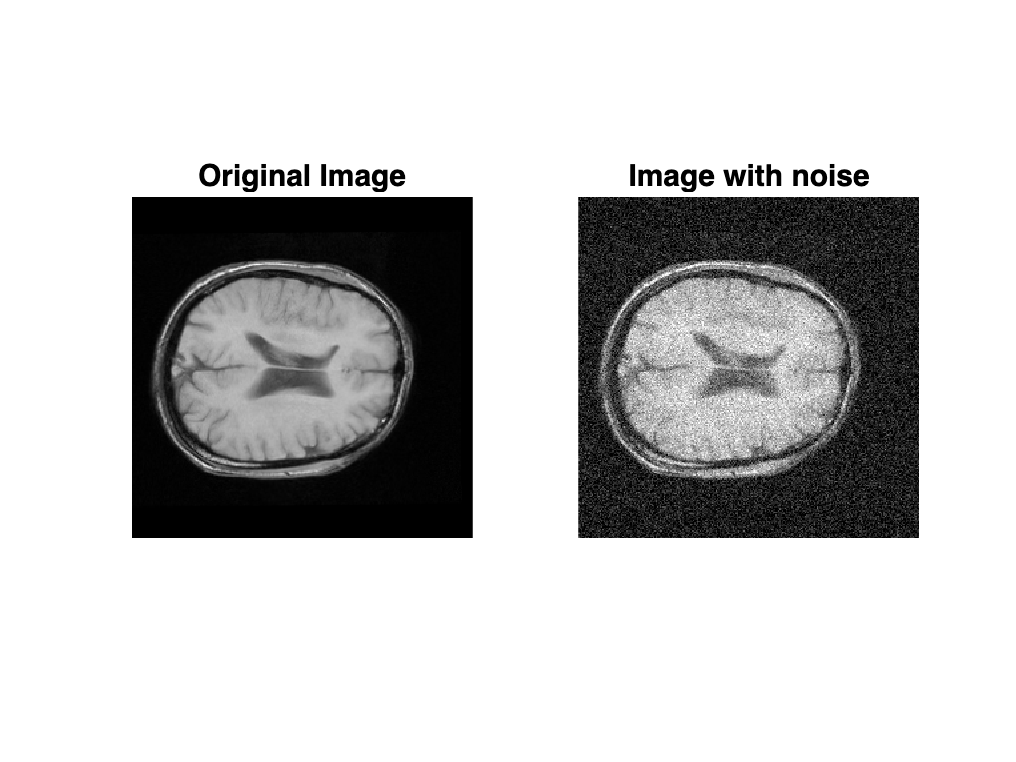


figure
subplot(1,2,1), imshow(image), title('Original Image')
subplot(1,2,2), imshow(img_w_noise), title('Image with noise')

Run this sectiono if you want to use the new image from now on


image = img_w_noise;


## Noise removal

You can see the effects of noise removal on your image

Next, you'll be able to choose which image to keep (the original or one of the noise-removal versions)

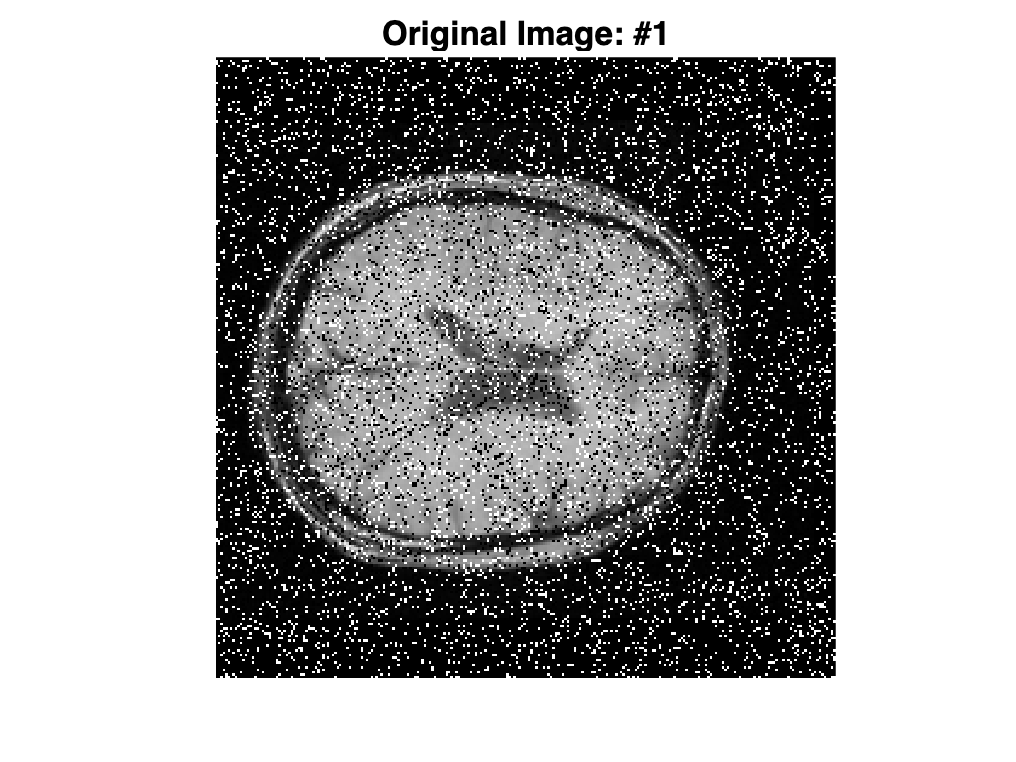


% avg filters
avg_filt_3 = 1/9.*ones(3,3);
avg_filt_5 = 1/25.*ones(5,5);
img_3avg  = imfilter(image, avg_filt_3, 'conv');
img_5avg  = imfilter(image, avg_filt_5, 'conv');

% median filters
img_3med  = medfilt2(image, [3 3]);
img_5med  = medfilt2(image, [5 5]);

% vector for user selection
img_noise_removing = zeros(size(image,1), size(image,2), 5);
img_noise_removing(:,:,1) = image;
img_noise_removing(:,:,2) = img_3avg;
img_noise_removing(:,:,3) = img_5avg;
img_noise_removing(:,:,4) = img_3med;
img_noise_removing(:,:,5) = img_5med;


% show results to the user
figure
imshow(image,[]), title('Original Image: #1')

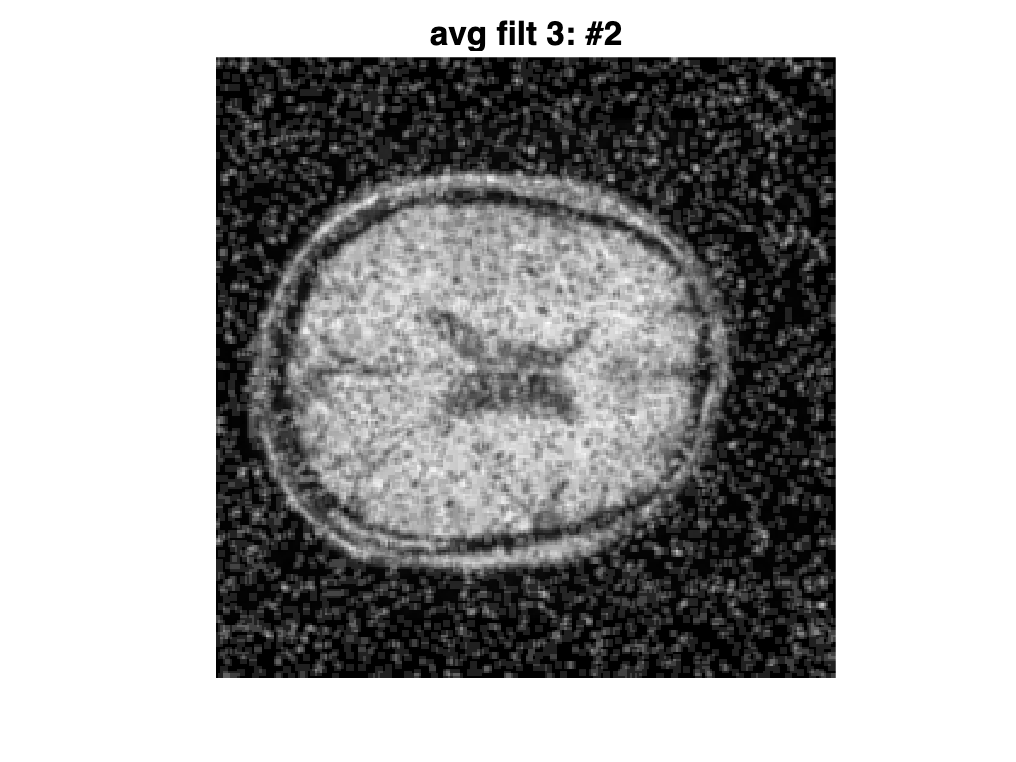


figure
imshow(img_3avg, []), title('avg filt 3: #2')

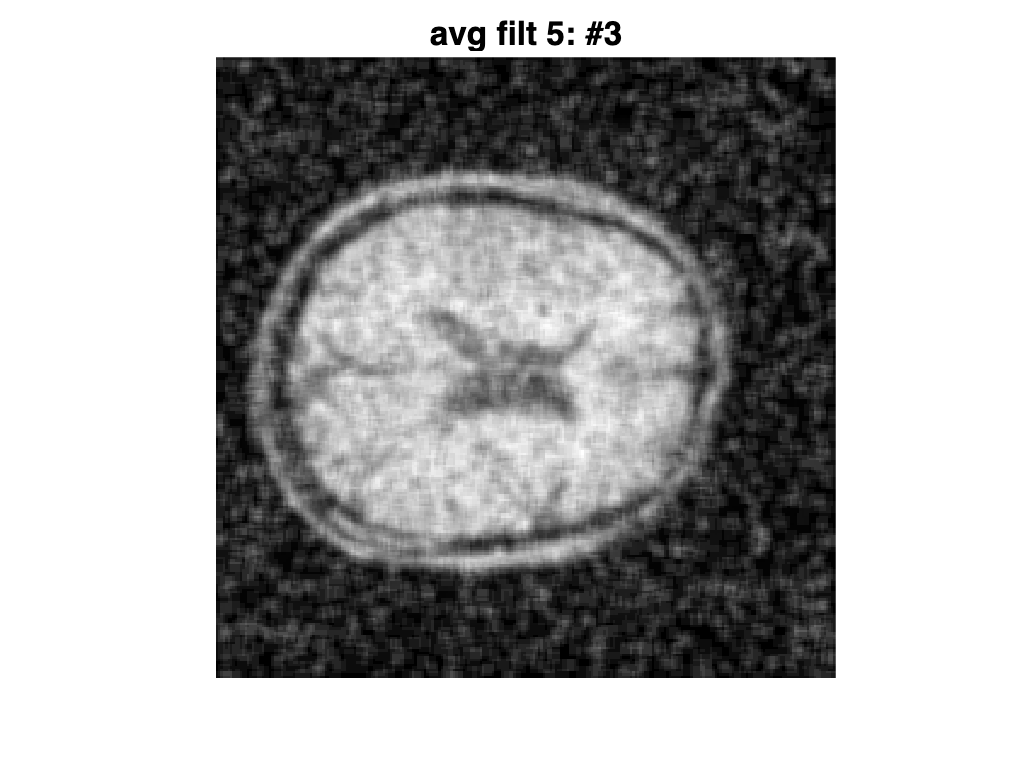


figure
imshow(img_5avg, []), title('avg filt 5: #3')

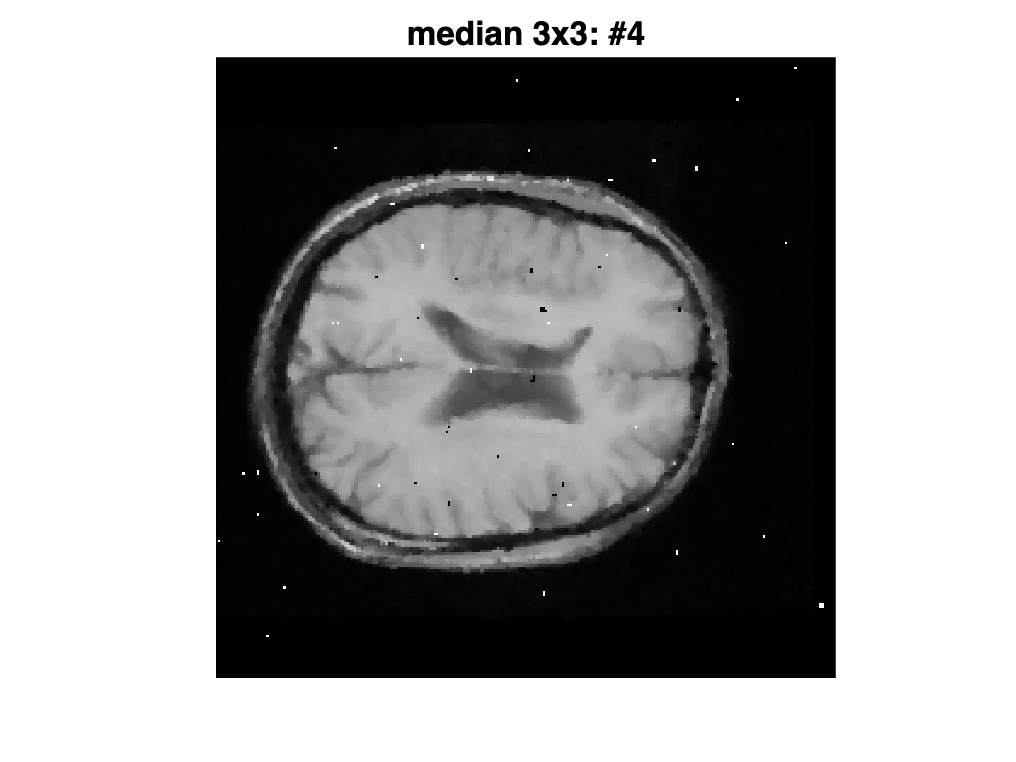


figure
imshow(img_3med, []), title('median 3x3: #4')

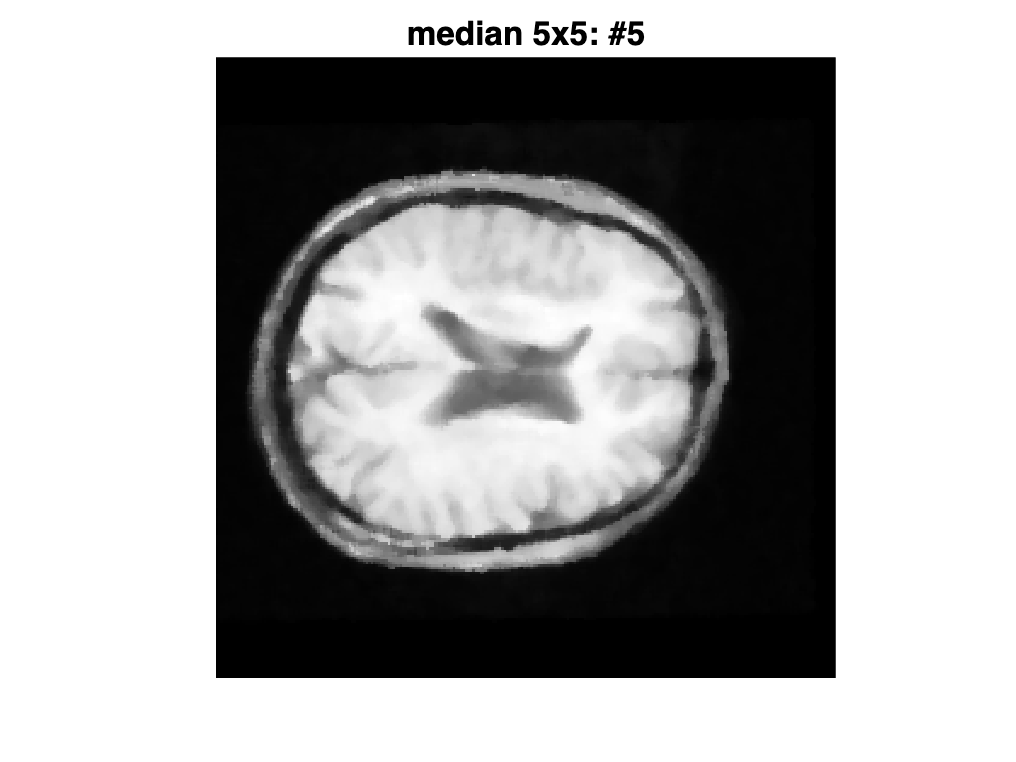


figure
imshow(img_5med, []), title('median 5x5: #5')

If you used Noise Removal, select the number corresponding to the image you want to use from now on


selected_index = 5 ;


-------------------------------------


image = img_noise_removing(:,:,selected_index);


## Personalized normalization

Here you can set the parameters for a new normalization


norm_min = 0 ;
norm_max = 0.8 ;


-------------------------------------

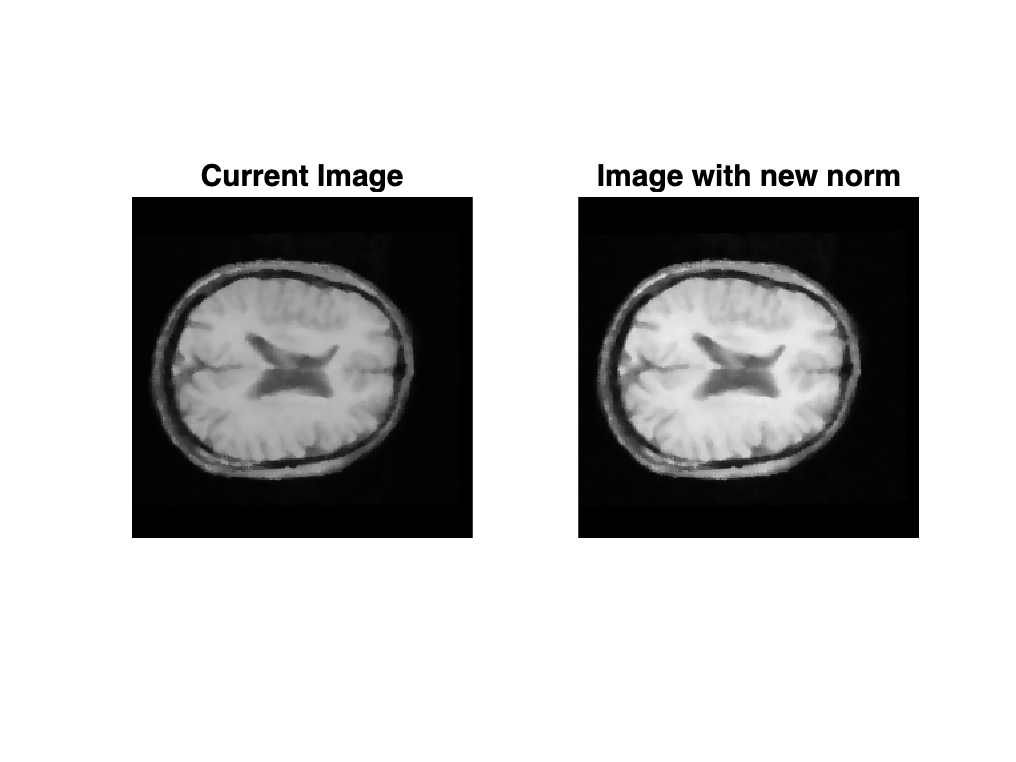


new_norm = ( image - norm_min )./( norm_max - norm_min );

figure
subplot(121), imshow(image); title('Current Image');
subplot(122), imshow(new_norm); title('Image with new norm');

Run this Section if you want to use the new image from now on


image = new_norm;


## Gamma function

Select gamma and the range in which you want to apply the gamma transformation, then Run this Section to see the resulting image compared with the original one


gamma = 1.8 ;
LOW_out = 0 ;
HIGH_out = 1 ;
LOW_in = 0;
HIGH_in = 1;


-------------------------------------

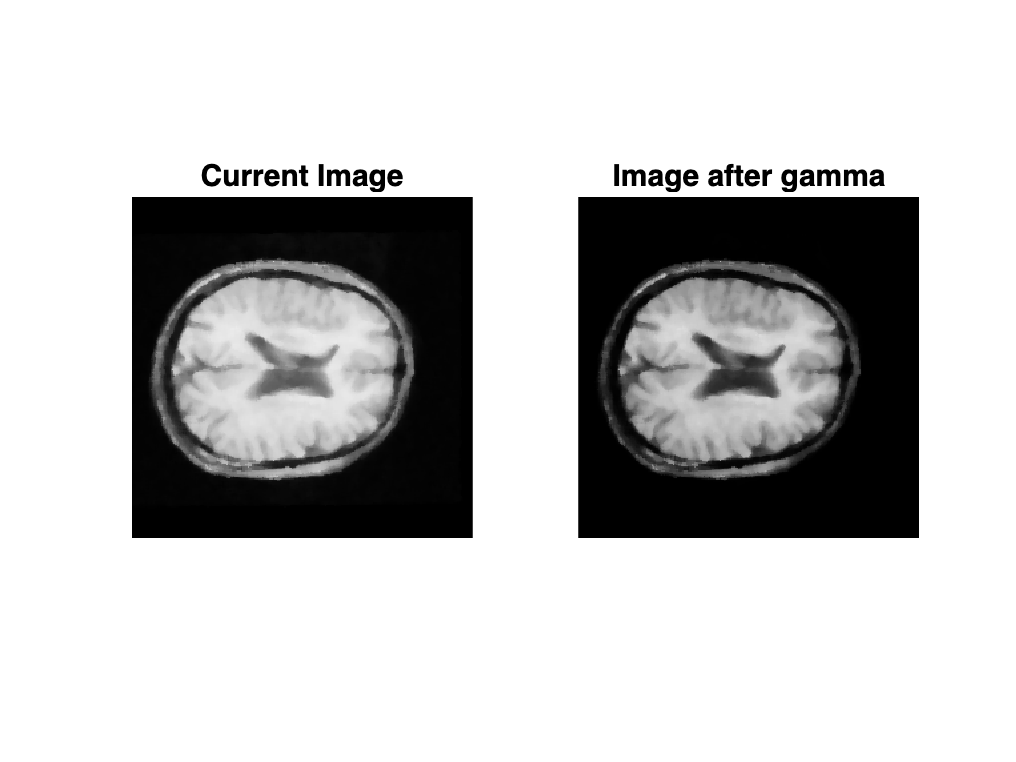


gamma_image = imadjust(image,[LOW_in HIGH_in],[LOW_out HIGH_out], gamma);

figure
subplot(121), imshow(image); title('Current Image');
subplot(122), imshow(gamma_image); title('Image after gamma');

Run this section if you want to use the new image from now on


image = gamma_image;


## Edge detection

Choose the mask you want to use by uncommenting the corresponding line (leave the others commented)

If you want, you can create a new mask


mask = [0 1 0; 0 0 0; 0 -1 0];
% mask = [1 2 1; 0 0 0; -2 -1 -1];
% mask = [ 1  2  3  2  1; 0  1  2  1  2; 0  0  0  0  0; 0 -1 -2 -2  1; -1 -2 -3 -2 -1];
% mask = [ build ; your ; mask ];


-------------------------------------

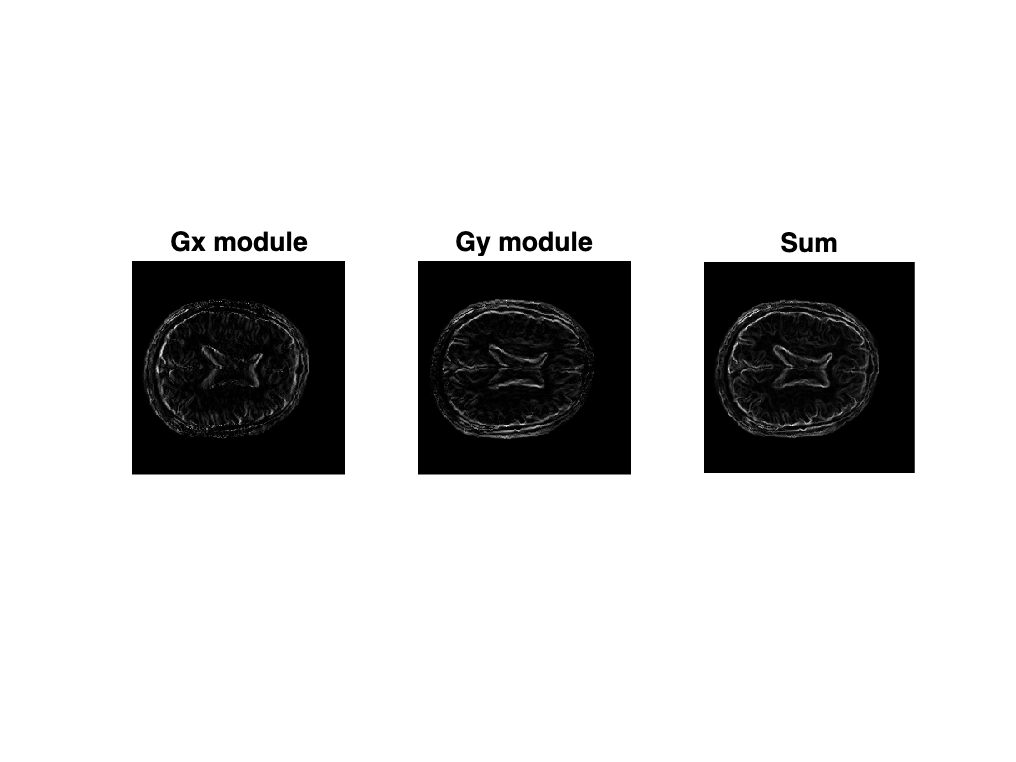


hy = mask ;
hx = mask';

% derivative computation in the two directions
Gx = imfilter(image, hx, 'conv');
Gy = imfilter(image, hy, 'conv');
img_modified_gradient = abs(Gx)+abs(Gy);

% absolute values
figure
subplot(131), imshow(abs(Gx), [], 'InitialMagnification', 'fit'), title('Gx module')
subplot(132), imshow(abs(Gy), [], 'InitialMagnification', 'fit'), title('Gy module')
subplot(133), imshow(img_modified_gradient, [], 'InitialMagnification', 'fit'), title('Sum')

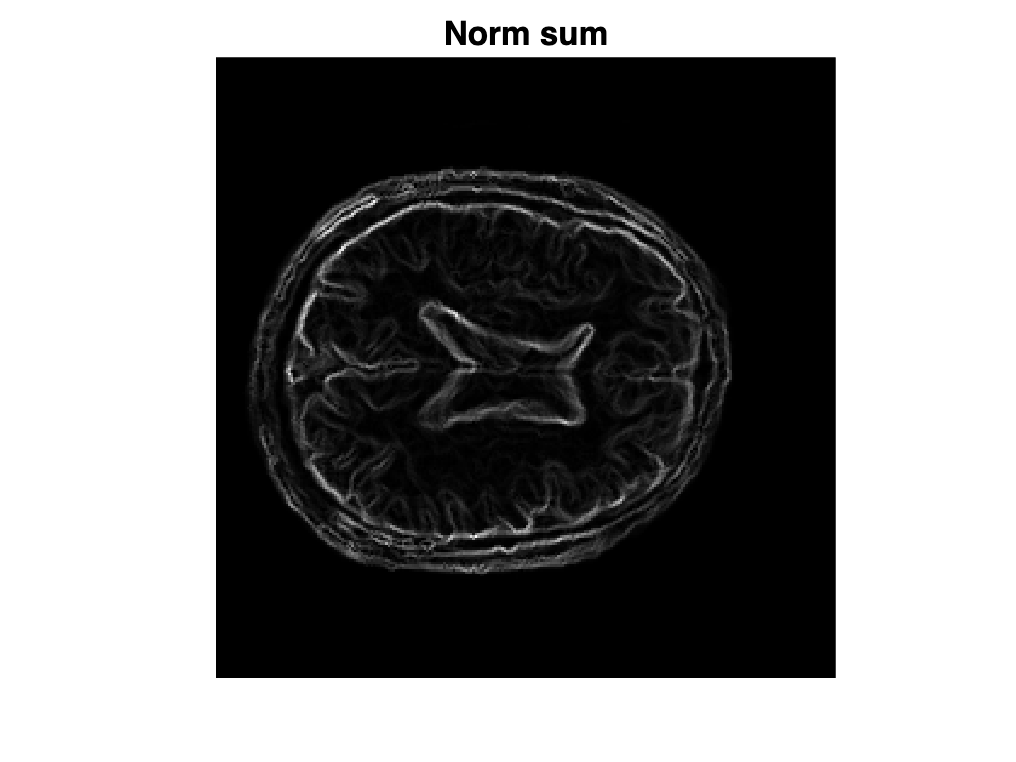


% norm sum
norm_sum = ( img_modified_gradient - min(img_modified_gradient(:)) )./( max(img_modified_gradient(:)) - min(img_modified_gradient(:)) );
figure
imshow(norm_sum);
title('Norm sum');

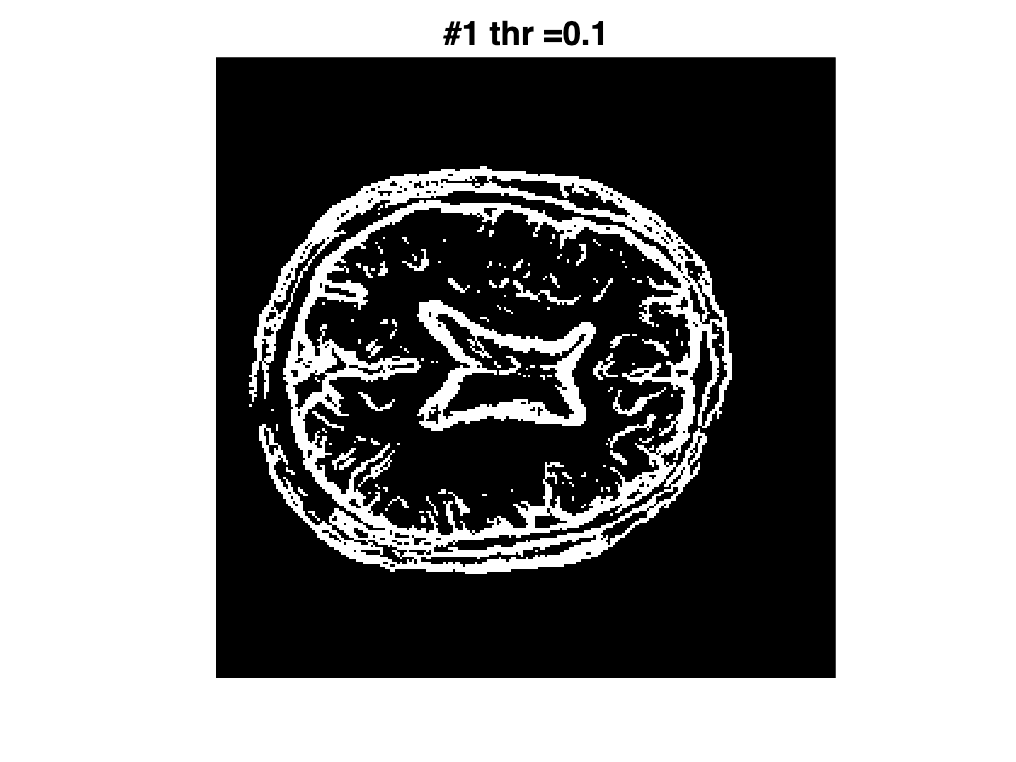

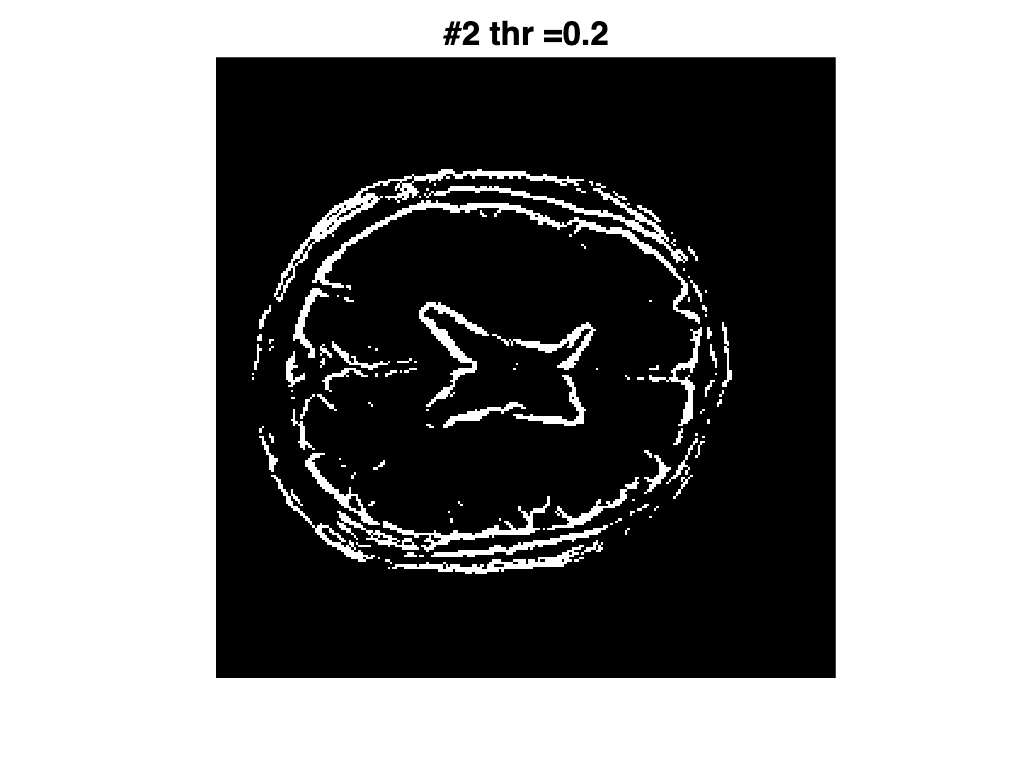

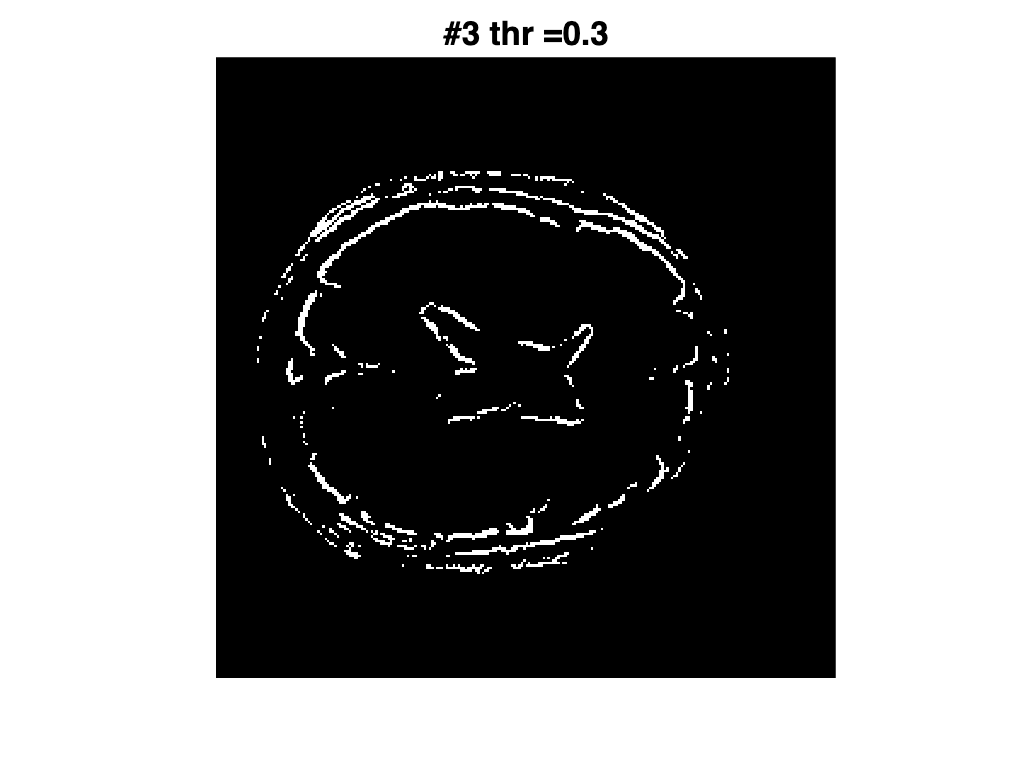

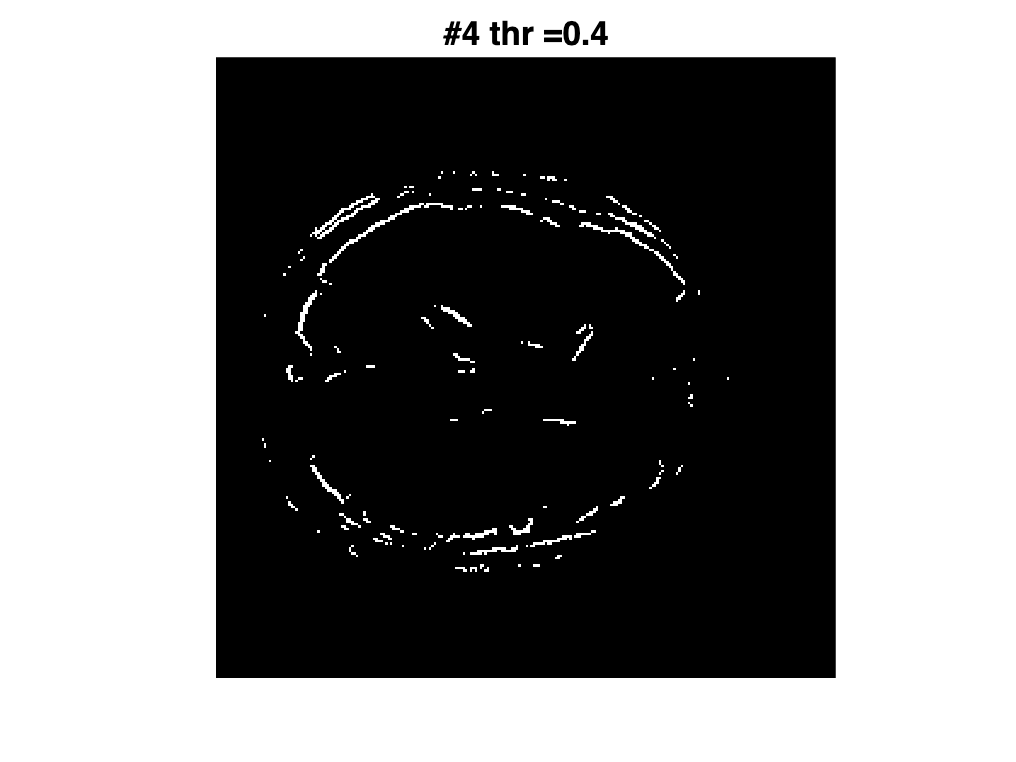

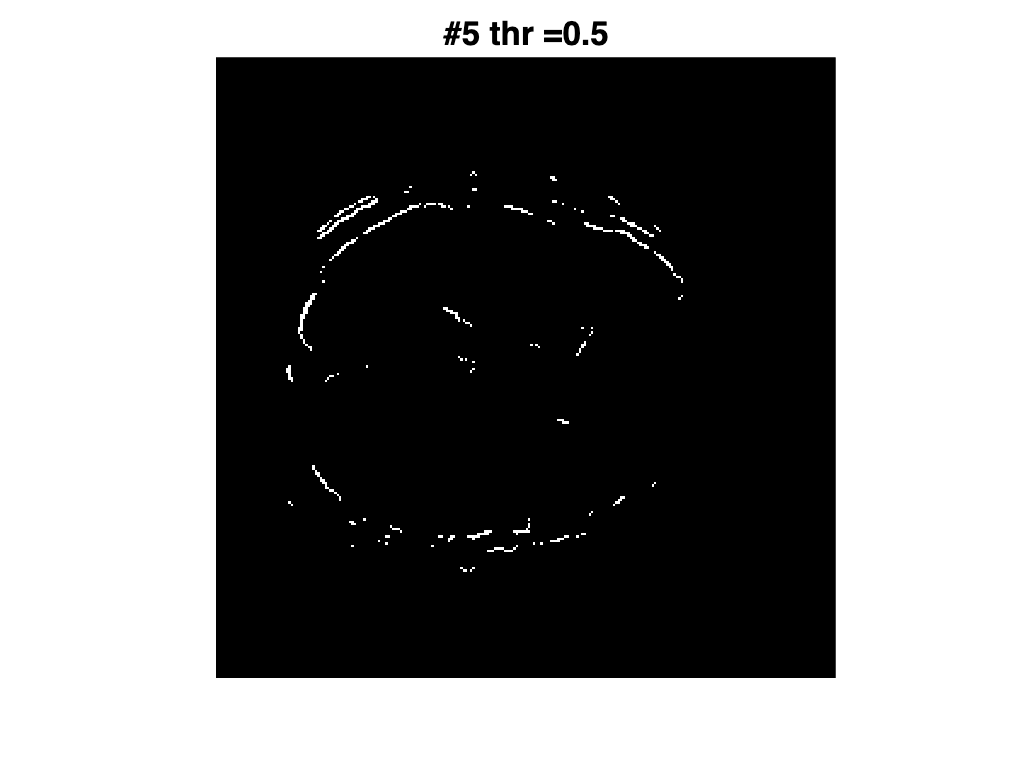

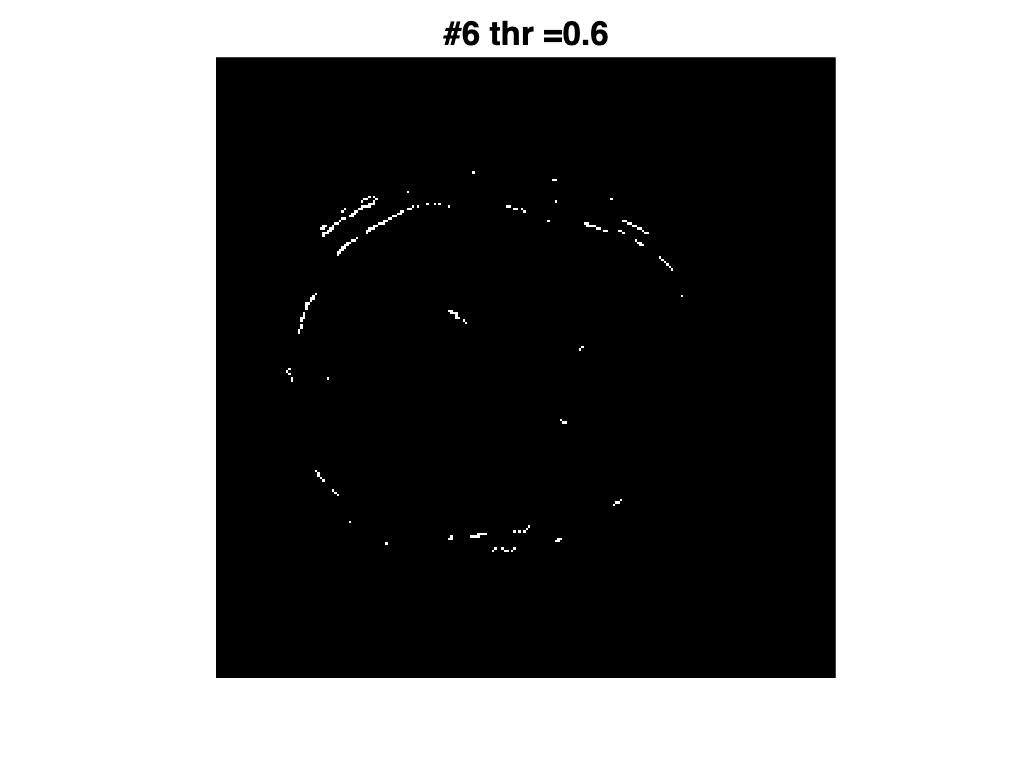

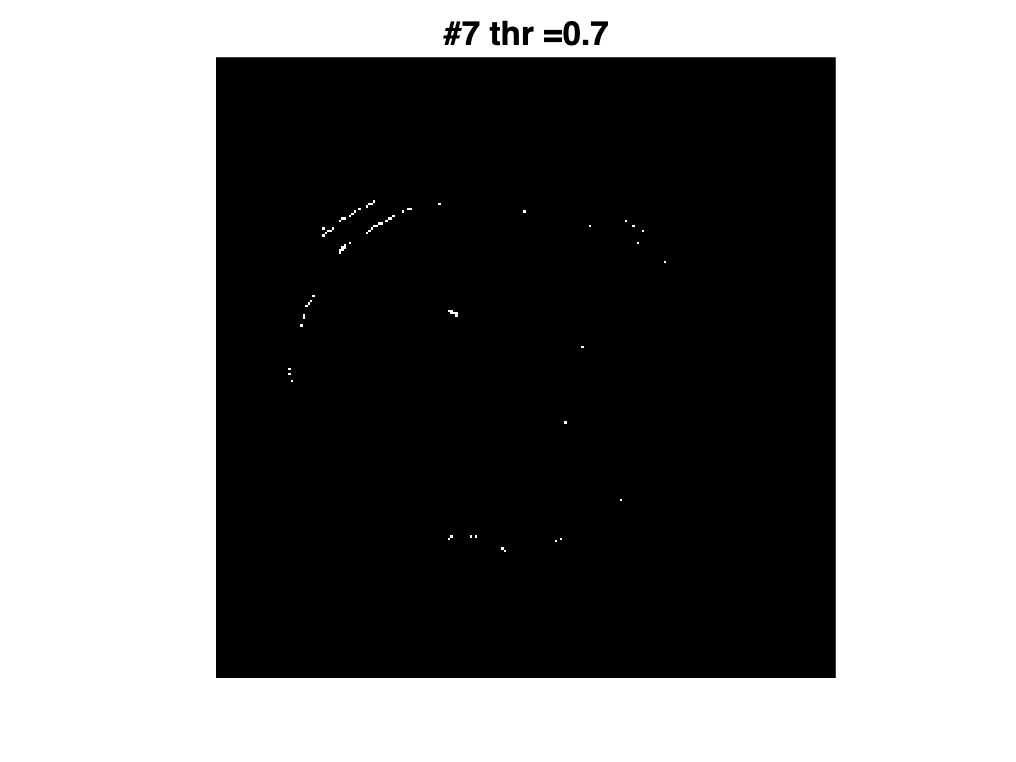

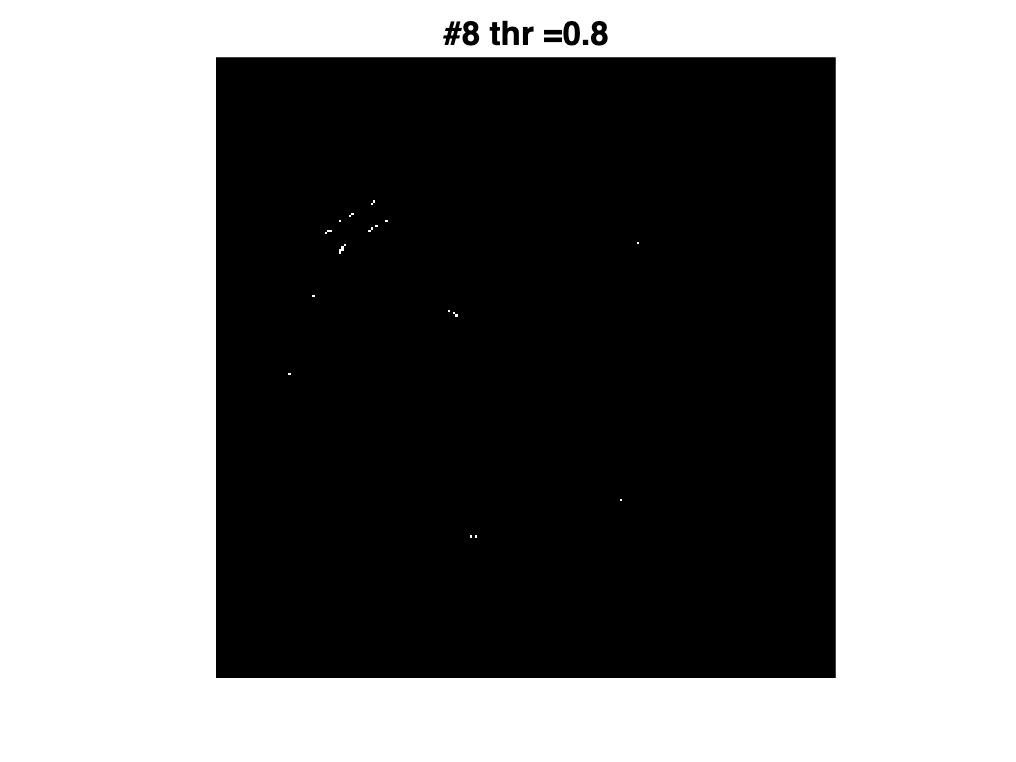


% several gradient thresholds
% threshold = linspace(0, max(image(:)), 11);
threshold = linspace(0, max(norm_sum(:)), 11);

img_edge = zeros(size(img_modified_gradient,1), size(img_modified_gradient,2), 11);

for i=2:length(threshold)
    figure
    img_to_show = imbinarize(img_modified_gradient, threshold(i));
    imshow(img_to_show);
    img_edge(:,:,i) = img_to_show;
    title( strcat('#', num2str(i-1), ' thr = ', num2str(threshold(i))) );
end

## Area computation

Image selection:

Among the images you see, input the one you want to be used for the computation of the ventricle area (must be between 1 and 10)

If you want to calculate the area using the image instead of the borders-images, set 0


selected_image_index = 4 ;


Then, double click inside the region of which you want to know the area

-------------------------------------

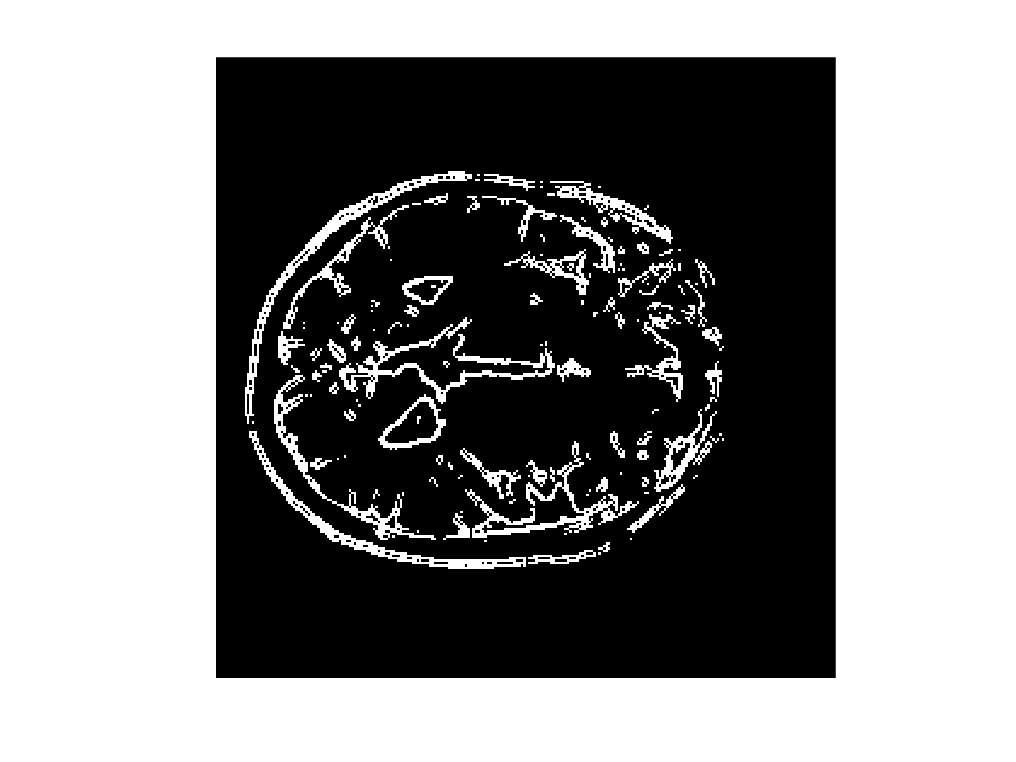


img_edge(:,:,1) = ~image;           % useful with some t2 images
selected_contoured_img = img_edge(:,:,selected_image_index+1);
imshow(selected_contoured_img);

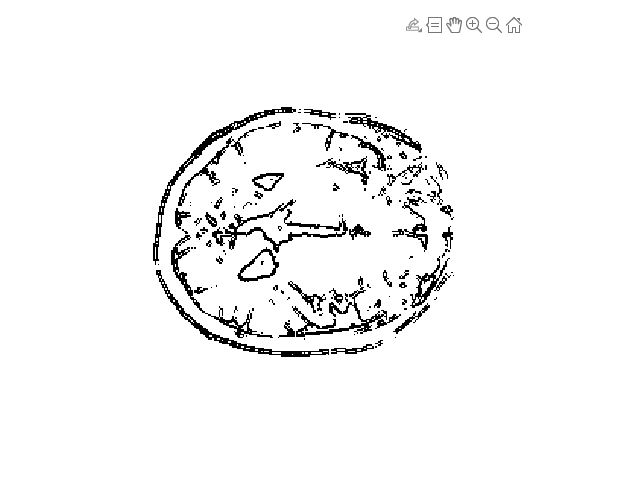

BW = bwselect(~selected_contoured_img,4);

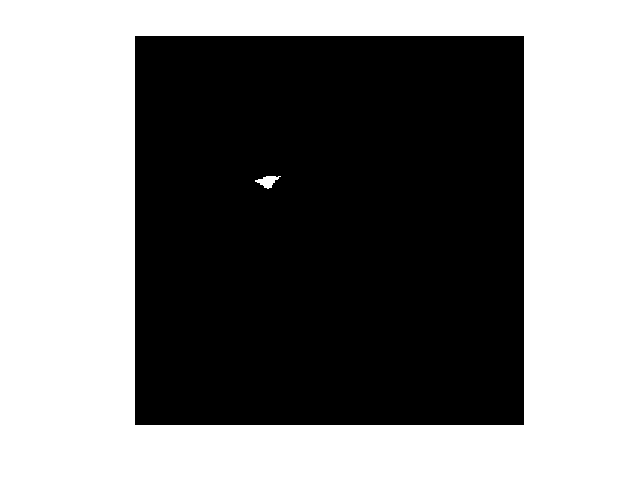

BW2 = imfill(BW,"holes");
imshow(BW2);

%Area_BW = length(find(BW))
Area = length(find(BW2))

Area = 79

## 3D image update

Indicate here which ventricle you selected (by commenting the other one)


selected_ventricle = 'right';
%selected_ventricle = 'left ';


then Run Section

-------------------------------------


if selected_ventricle == 'right'
    right_ventricle_volume(:,:,slice_number) = right_ventricle_volume(:,:,slice_number) + BW2;
else
    left_ventricle_volume(:,:,slice_number)  = left_ventricle_volume(:,:,slice_number)  + BW2;
end


## Volume computation


total_white_voxels_right_ventricle = length(find(right_ventricle_volume(:,:,:)));
right_volume = total_white_voxels_right_ventricle * voxel_dim;
fprintf('Volume of right ventricle is %f Cubed %s' , right_volume, dimension );

Volume of right ventricle is 26068.661981 Cubed Millimeter


total_white_voxels_left_ventricle = length(find(left_ventricle_volume(:,:,:)));
left_volume = total_white_voxels_left_ventricle * voxel_dim;
fprintf('Volume of left ventricle is %f Cubed %s' , left_volume, dimension );

Volume of left ventricle is 0.000000 Cubed Millimeter

## Slice 16 segmentation performance

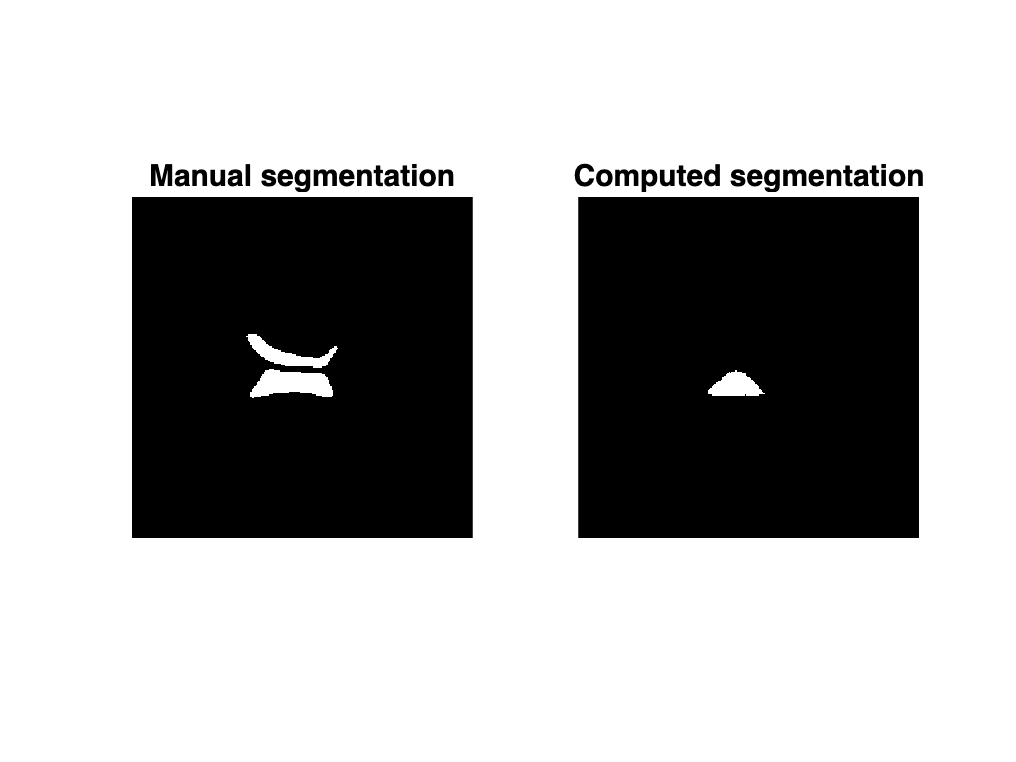


BW_manual_segm = imbinarize(imread("BW_manual_segmentation.jpg"));
BW_computed_segm = BW2 ;
% BW_computed_segm = imbinarize(imread("BW_computed_segmentation.jpg"));
% uncomment next line to test with slice 16 found by you
%BW_computed_segm = right_ventricle_volume(:,:,16) + left_ventricle_volume(:,:,16);

figure
subplot(1,2,1), imshow(BW_manual_segm), title("Manual segmentation");
subplot(1,2,2), imshow(BW_computed_segm), title("Computed segmentation");


TP = 0;
TN = 0;
FP = 0;
FN = 0;

for i=1:256
    for j=1:256
        if BW_manual_segm(i,j) == 1
            if BW_computed_segm(i,j) == 1
                TP = TP + 1;
            else
                FN = FN + 1;
            end
        else
            if BW_computed_segm(i,j) == 1
                FP = FP + 1;
            else
                TN = TN + 1;
            end
        end
    end
end

sensitivity = TP / (TP+FN)

sensitivity = 0.2934

specificity = TN / (TN+FP)

specificity = 0.9989

dice_coeff  = 2*TP / ( 2*TP + FP + FN)

dice_coeff = 0.4382


TP = 0;
TN = 0;
FP = 0;
FN = 0;


% same copmutation but with pixels from (50,50) to (200,200)
for i=100:157
    for j=86:156
        if BW_manual_segm(i,j) == 1
            if BW_computed_segm(i,j) == 1
                TP = TP + 1;
            else
                FN = FN + 1;
            end
        else
            if BW_computed_segm(i,j) == 1
                FP = FP + 1;
            else
                TN = TN + 1;
            end
        end
    end
end

sensitivity_on_restricted_region = TP / (TP+FN)

sensitivity_on_restricted_region = 0.2934

specificity_on_restricted_region = TN / (TN+FP)

specificity_on_restricted_region = 0.9729

dice_coeff_on_restricted_region  = 2*TP / ( 2*TP + FP + FN)

dice_coeff_on_restricted_region = 0.4382